# Grid_Frequency_Measurements_of_the_50_Hz_Japanese_Power_System_during_2020

https://data.dtu.dk/articles/dataset/Grid_Frequency_Measurements_of_the_50_Hz_Japanese_Power_System_during_2020/14038910

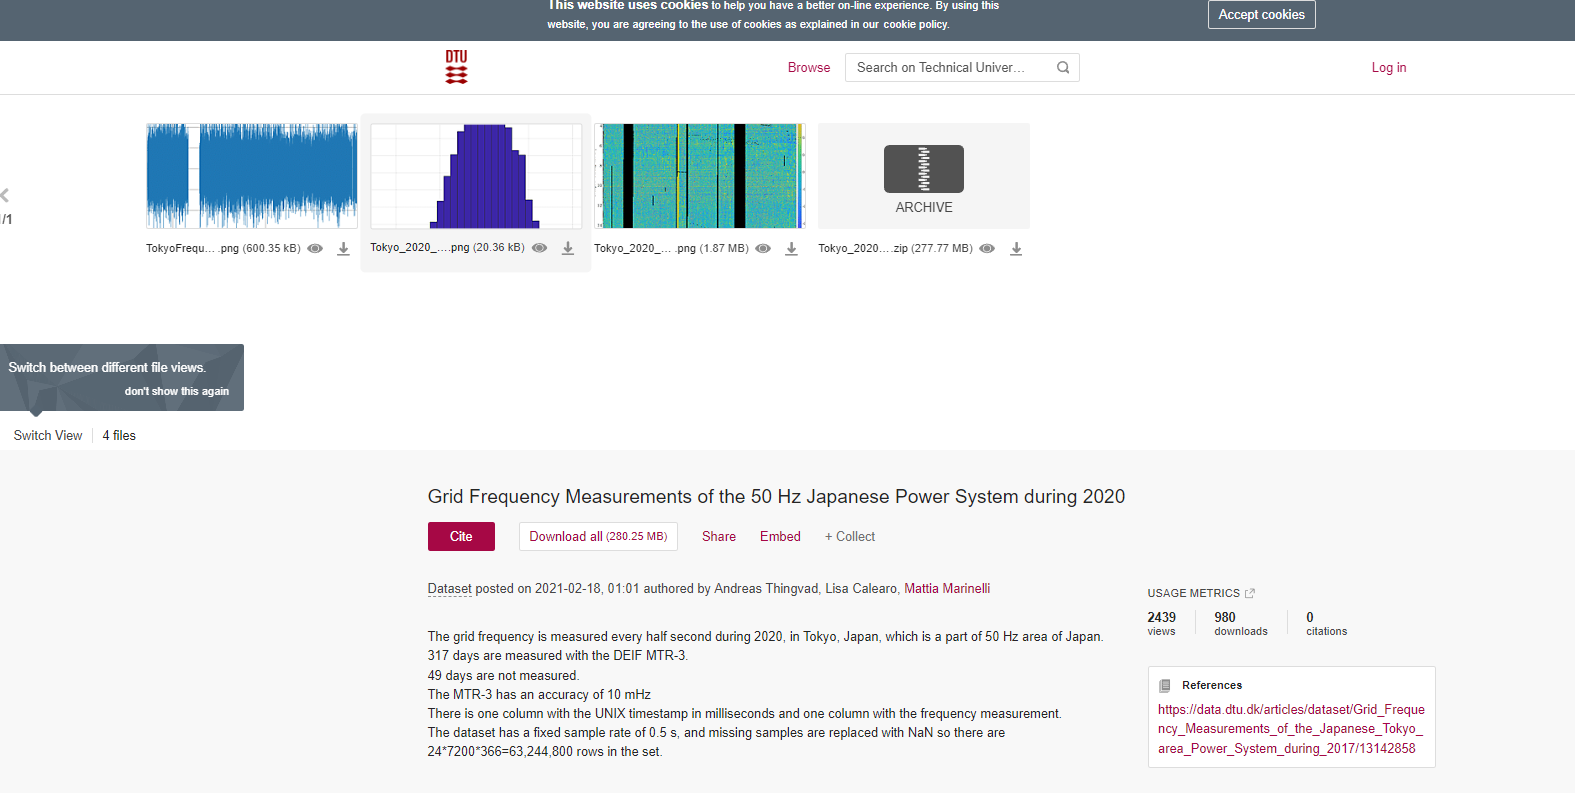

## ファイルダウンロードと処理

websave関数を用いてファイルをダウンロード

data=websave('Tokyo_2020.csv.zip','https://data.dtu.dk/ndownloader/files/26485760');

zipファイルの解凍・不要なファイルの削除

unzip('Tokyo_2020.csv.zip');
filename=fullfile('__MACOSX','._Tokyo_2020.csv');
delete(filename);
rmdir('__MACOSX');

## 全期間のファイルをmat保存

'Tokyo_2020.csv'ファイルをMATLABに読み込む

filename='Tokyo_2020.csv';

'Tokyo_2020.csv'ファイルのプロパティ

opt=detectImportOptions(filename,'FileType','text','VariableNamingRule','preserve');

1列目はタイムスタンプ（整数）、2列目が値であるが、変数が膨大になるため、1列目は整数uint64、2列目は単精度singleで保存

opt.VariableTypes={'uint64','single'};
preview(filename,opt)

ans = 8×2 table
      timestamp       freq 
    _____________    ______

    1577836800000        50
    1577836800000        50
    1577836841987    49.937
    1577836842237    49.936
    1577836842737    49.934
    1577836843237    49.933
    1577836843738    49.932
    1577836844238    49.931


readtable関数でテーブル読み込み

tbl=readtable(filename,opt);

datetime関数を用いてタイムスタンプを時刻データに変換

Time=datetime(tbl.timestamp/1000,'ConvertFrom','posixtime');

table2timetable関数を用いて時刻変数Timeを行の時刻としたタイムテーブルに変換

TT= table2timetable(tbl(:,2),"RowTimes",Time);

出力するファイル名の作成、matファイルに保存

[~,name]=fileparts(filename);

save([name,'.mat'],'TT','-v7.3');


## 特定の期間のみを保存（推奨）

上記のセクションのmatファイルは膨大であるため、必要な時刻のみを抽出

load([name,'.mat']);

sDay=datetime("2020-04-01", "InputFormat", "uuuu-MM-dd");
eDay=datetime("2020-04-07", "InputFormat", "uuuu-MM-dd");

開始日～終了日のデータ期間trを設定

tr=timerange(sDay,eDay,'closed');

TTの期間変更

TT=TT(tr,:);

期間を限定したmatファイルの作成・保存

sTime=TT.Time(1);
eTime=TT.Time(end);

filename="Tokyo_2020"+ string(sTime,"MMdd") + "-" + string(eTime,"MMdd") +".mat";

save(filename,'TT','-v7.3');
